clear
close all

## Cargar los datos de entrenamiento

data_train = load('PisosTrain.txt');
y_train = data_train(:,3);  % Precio en Euros
x1_train = data_train(:,1); % m^2
x2_train = data_train(:,2); % Habitaciones
N_train = length(y_train);

## Cargar los datos de test

data_test = load('PisosTest.txt');
y_test = data_test(:,3);  % Precio en Euros
x1_test = data_test(:,1); % m^2
x2_test = data_test(:,2); % Habitaciones
N_test = length(y_test);

## 2. Regresión monovariable en función de la superficie usando ecuación normal

figure;
plot(x1_train, y_train, 'bx');
title('Precio de los Pisos')
ylabel('Euros'); xlabel('Superficie (m^2)');
grid on; hold on;

X_train = [ones(N_train,1) x1_train];
th = X_train \ y_train;  % Aplicar ecuación normal
fprintf("%2f + %2f*x1\n", th);

-34313.387972 + 2608.209435*x1


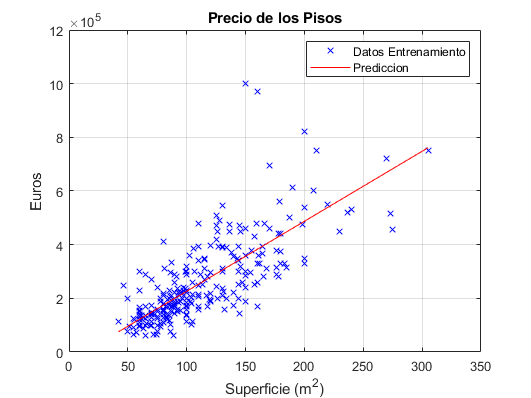

Xextr_train = [1 min(x1_train)  % Predicción para los valores extremos
    1 max(x1_train)];
yextr_train = Xextr_train * th;
plot(Xextr_train(:,2), yextr_train, 'r-'); % Dibujo la recta de predicción
xlim([0 350]);
ylim([0 12*10^5]);
legend('Datos Entrenamiento', 'Prediccion')

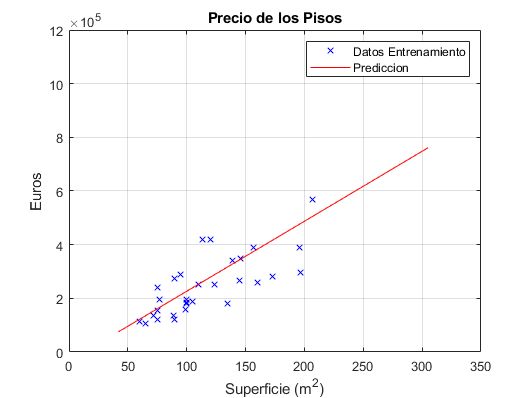


% Dibujar los datos de test
X_test = [ones(N_test,1) x1_test];

% Gráfica con los datos de test y la recta de predicción calculada
figure;
plot(x1_test, y_test, 'bx');
title('Precio de los Pisos')
ylabel('Euros'); xlabel('Superficie (m^2)');
grid on; hold on;
plot(Xextr_train(:,2), yextr_train, 'r-');
xlim([0 350]);
ylim([0 12*10^5]);
legend('Datos Entrenamiento', 'Prediccion')


% Cálculo del error RMS para los datos de entrenamiento
rmse_train = sqrt(calcularSSE(th,X_train,y_train) / N_train);
fprintf("RMSE Train data: %2f\n", rmse_train);

RMSE Train data: 102739.708064



% Cálculo del error RMS para los datos de test
rmse_test = sqrt(calcularSSE(th,X_test,y_test) / N_test);
fprintf("RMSE Test data: %2f\n", rmse_test);

RMSE Test data: 80628.544728



estimarPrecioMonov = @(x) -34313.387872 + 2608.209435*x;
precio = estimarPrecioMonov(100);
fprintf("Precio piso 100 m2 = %2f\n", precio);

Precio piso 100 m2 = 226507.555628


## 3. Regresión multivariable con ecuación normal

X_train = [ones(N_train,1) x1_train x2_train];

%Normalilzar
N = size(X_train,1);
mu = mean(X_train(:,2:end));
sig = std(X_train(:,2:end));
X_train(:,2:end) = (X_train(:,2:end) - repmat(mu,N,1))./ repmat(sig,N,1);

th = X_train \ y_train;  % Aplicar ecuación normal
yest_train = X_train * th;

%Des-normalizar
th(2:end) = th(2:end)./sig';
th(1) = th(1)-(mu * th(2:end));
fprintf("%2f + %2f*x1 + %2f*x2\n", th);

-12132.908900 + 3028.744415*x1 + -18852.830946*x2


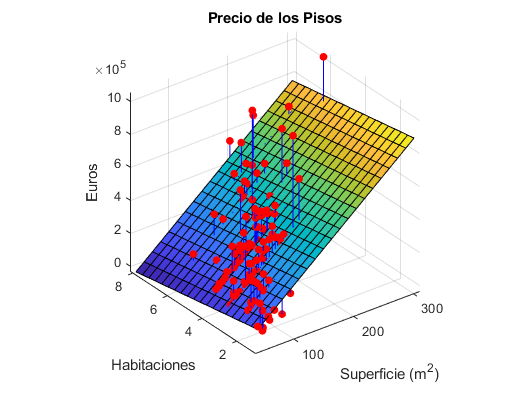


% Dibujar los puntos de entrenamiento y su valor estimado
figure;
plot3(x1_train, x2_train, y_train, '.r', 'markersize', 20);
axis vis3d; hold on;
plot3([x1_train x1_train]' , [x2_train x2_train]' , [y_train yest_train]', '-b');

% Generar una retícula de np x np puntos para dibujar la superficie
np = 20;
ejex1 = linspace(min(x1_train), max(x1_train), np)';
ejex2 = linspace(min(x2_train), max(x2_train), np)';
[x1g,x2g] = meshgrid(ejex1, ejex2);
x1g = x1g(:); %Los pasa a vectores verticales
x2g = x2g(:);

% Calcula la salida estimada para cada punto de la retícula
Xg = [ones(size(x1g)), x1g, x2g];
yg = Xg * th;

% Dibujar la superficie estimada
surf(ejex1, ejex2, reshape(yg,np,np)); grid on;
title('Precio de los Pisos')
zlabel('Euros'); xlabel('Superficie (m^2)'); ylabel('Habitaciones');


X_test = [ones(N_test,1) x1_test x2_test];

% Cálculo del error RMS para los datos de entrenamiento
rmse_train = sqrt(calcularSSE(th,X_train,y_train) / N_train);
fprintf("RMSE Train data: %2f\n", rmse_train);

RMSE Train data: 319546.462874



% Cálculo del error RMS para los datos de test
rmse_test = sqrt(calcularSSE(th,X_test,y_test) / N_test);
fprintf("RMSE Test data: %2f\n", rmse_test);

RMSE Test data: 74740.529167



estimarPrecioMultiv = @(x1,x2) -12132.908900 + 3028.744415*x1 - 18852.830946*x2;
precio2 = estimarPrecioMultiv(100,2);
precio3 = estimarPrecioMultiv(100,3);
precio4 = estimarPrecioMultiv(100,4);
precio5 = estimarPrecioMultiv(100,5);

fprintf("Precio piso 100 m2 = %2f\n", precio2);

Precio piso 100 m2 = 253035.870708


fprintf("Precio piso 100 m2 = %2f\n", precio3);

Precio piso 100 m2 = 234183.039762


fprintf("Precio piso 100 m2 = %2f\n", precio4);

Precio piso 100 m2 = 215330.208816


fprintf("Precio piso 100 m2 = %2f\n", precio5);

Precio piso 100 m2 = 196477.377870


## 4.Regresión monovariable en función de la superficie con descenso de gradiente

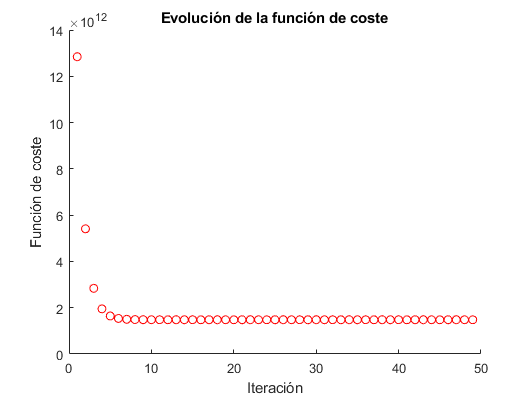

X_train = [ones(N_train,1) x1_train];
th = [0 0]';  % valores cualquiera de theta
alpha = 0.0000001;

figure;
hold on;
title('Evolución de la función de coste')
ylabel('Función de coste'); xlabel('Iteración');
xlim([0 50]);

% Aplicar descenso de gradiente
[J1,grad] = costeL2(th, X_train, y_train);
i=1;
plot(i,J1,'ro');
th = th - alpha*grad;
[J2,grad] = costeL2(th, X_train, y_train);
while (J2 < J1)
    J1 = J2;
    i = i+1;
    if(i < 50)
        plot(i,J1,'ro');
    end
    th = th - alpha*grad;
    [J2,grad] = costeL2(th, X_train, y_train);
end

fprintf("%2f + %2f*x1\n", th);

-34310.964281 + 2608.191099*x1



X_test = [ones(N_test,1) x1_test];

% Cálculo del error RMS para los datos de entrenamiento
rmse_train = sqrt(calcularSSE(th,X_train,y_train) / N_train);
fprintf("RMSE Train data: %2f\n", rmse_train);

RMSE Train data: 102739.708068



% Cálculo del error RMS para los datos de test
rmse_test = sqrt(calcularSSE(th,X_test,y_test) / N_test);
fprintf("RMSE Test data: %2f\n", rmse_test);

RMSE Test data: 80628.396938


## 5. Regresión multivariable con descenso de gradiente

X_train = [ones(N_train,1) x1_train x2_train];
th = [0 0 0]';  % valores cualquiera de theta
alpha = 0.0000001;

%Normalilzar
N = size(X_train,1);
mu = mean(X_train(:,2:end));
sig = std(X_train(:,2:end));
X_train(:,2:end) = (X_train(:,2:end) - repmat(mu,N,1))./ repmat(sig,N,1);

% Aplicar descenso de gradiente
[J1,grad] = costeL2(th, X_train, y_train);
th = th - alpha*grad;
[J2,grad] = costeL2(th, X_train, y_train);
while (J2 < J1)
    J1 = J2;
    th = th - alpha*grad;
    [J2,grad] = costeL2(th, X_train, y_train);
end

yest_train = X_train * th;

%Des-normalizar
th(2:end) = th(2:end)./sig';
th(1) = th(1)-(mu * th(2:end));
fprintf("%2f + %2f*x1 + %2f*x2\n", th);

-12133.172179 + 3028.722615*x1 + -18852.093512*x2


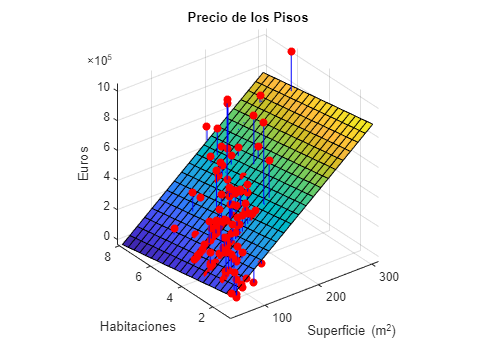


% Dibujar los puntos de entrenamiento y su valor estimado
figure;
plot3(x1_train, x2_train, y_train, '.r', 'markersize', 20);
axis vis3d; hold on;
plot3([x1_train x1_train]' , [x2_train x2_train]' , [y_train yest_train]', '-b');

% Generar una retícula de np x np puntos para dibujar la superficie
np = 20;
ejex1 = linspace(min(x1_train), max(x1_train), np)';
ejex2 = linspace(min(x2_train), max(x2_train), np)';
[x1g,x2g] = meshgrid(ejex1, ejex2);
x1g = x1g(:); %Los pasa a vectores verticales
x2g = x2g(:);

% Calcula la salida estimada para cada punto de la retícula
Xg = [ones(size(x1g)), x1g, x2g];
yg = Xg * th;

% Dibujar la superficie estimada
surf(ejex1, ejex2, reshape(yg,np,np)); grid on;
title('Precio de los Pisos')
zlabel('Euros'); xlabel('Superficie (m^2)'); ylabel('Habitaciones');


X_test = [ones(N_test,1) x1_test x2_test];

% Cálculo del error RMS para los datos de entrenamiento
rmse_train = sqrt(calcularSSE(th,X_train,y_train) / N_train);
fprintf("RMSE Data train: %2f\n", rmse_train);

RMSE Data train: 319546.472633



% Cálculo del error RMS para los datos de test
rmse_test = sqrt(calcularSSE(th,X_test,y_test) / N_test);
fprintf("RMSE Data test: %2f\n", rmse_test);

RMSE Data test: 74740.572288


## 6. Regresión robusta con coste de Huber

X_train = [ones(N_train,1) x1_train x2_train];
th = [0 0 0]';  % valores cualquiera de theta
alpha = 0.000001;

%Normalilzar
N = size(X_train,1);
mu = mean(X_train(:,2:end));
sig = std(X_train(:,2:end));
X_train(:,2:end) = (X_train(:,2:end) - repmat(mu,N,1))./ repmat(sig,N,1);

% Aplicar descenso de gradiente
d = 100000;
[J1,grad] = costeHuber(th, X_train, y_train,d);
th = th - alpha*grad;
[J2,grad] = costeHuber(th, X_train, y_train,d);
while (J2 < J1)
    J1 = J2;
    th = th - alpha*grad;
    [J2,grad] = costeHuber(th, X_train, y_train,d);
end

yest_train = X_train * th;

%Des-normalizar
th(2:end) = th(2:end)./sig';
th(1) = th(1)-(mu * th(2:end));
fprintf("%2f + %2f*x1 + %2f*x2\n", th);

-7727.527378 + 2774.122235*x1 + -15069.306429*x2


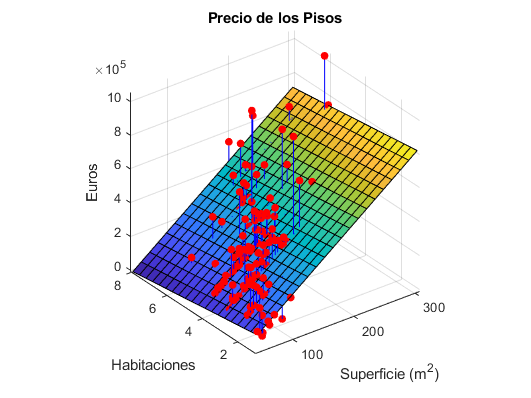


% Dibujar los puntos de entrenamiento y su valor estimado
figure;
plot3(x1_train, x2_train, y_train, '.r', 'markersize', 20);
axis vis3d; hold on;
plot3([x1_train x1_train]' , [x2_train x2_train]' , [y_train yest_train]', '-b');

% Generar una retícula de np x np puntos para dibujar la superficie
np = 20;
ejex1 = linspace(min(x1_train), max(x1_train), np)';
ejex2 = linspace(min(x2_train), max(x2_train), np)';
[x1g,x2g] = meshgrid(ejex1, ejex2);
x1g = x1g(:); %Los pasa a vectores verticales
x2g = x2g(:);

% Calcula la salida estimada para cada punto de la retícula
Xg = [ones(size(x1g)), x1g, x2g];
yg = Xg * th;

% Dibujar la superficie estimada
surf(ejex1, ejex2, reshape(yg,np,np)); grid on;
title('Precio de los Pisos')
zlabel('Euros'); xlabel('Superficie (m^2)'); ylabel('Habitaciones');


X_test = [ones(N_test,1) x1_test x2_test];

% Cálculo del error RMS para los datos de entrenamiento
rmse_train = sqrt(calcularSSE(th,X_train,y_train) / N_train);
fprintf("RMSE Data train: %2f\n", rmse_train);

RMSE Data train: 314763.993555



% Cálculo del error RMS para los datos de test
rmse_test = sqrt(calcularSSE(th,X_test,y_test) / N_test);
fprintf("RMSE Data test: %2f\n", rmse_test);

RMSE Data test: 70831.375330
